 clear
 clc

%Set Values
 FreeNormVel = 10; % The velocity of wind tunnel (m/s)
 N = 2; % Number Of fans
 row = 1.204;
 kVisc = 1.506e-5;
 Diameter = 0.5;
 slices = 100;
 Mach = 30/343;
 Ncrit = 5;
 aopt = 1/3;
 RootStart = 0.035;
 adashopt = 0.02;
 
 ReInit = [59000,57000]

ReInit =        59000       57000


 AirfoilChangeR = Diameter/8; %Turn into an array if more than one change

% for i = 1:(length(AirfoilChangeR)+1)
%      [XFOILA1,DesAlpha(i)] = run_xfoil(SG60(:,((i*2)-1):(i*2)), ReInit(i), Mach, Ncrit, min(alpha_grid), max(alpha_grid)); %Idk why warning it seems to work 
%  %Calculated from XFOIL data
%   ForTwstGrphAlpha = DesAlpha;
%  [~,idx] = min(abs(XFOILA1(:,1)-DesAlpha(i)));
%  LiftCoef(i) = XFOILA1(idx,2);
%  end

% ONLY RUN THIS ONCE

 % Sample airfoil coordinates (x, y)
SG60(:,1:2) = table2array(readtable('SG6040cords.csv','PreserveVariableNames',true));
SG60(:,3:4) = table2array(readtable('SG6043cords.csv','PreserveVariableNames',true));

% Example ranges
Re_grid = logspace(4.3, 5.05, 10);        % 10 values 
alpha_grid = linspace(-10, 25, 31);  % -10 to 20 degrees
DesAlpha_table = zeros((length(AirfoilChangeR)+1), length(Re_grid));
for i = 1:(length(AirfoilChangeR)+1)
     [XFOILA1,DesAlpha(i)] = run_xfoil(SG60(:,((i*2)-1):(i*2)), ReInit(i), Mach, Ncrit, min(alpha_grid), max(alpha_grid)); %Idk why warning it seems to work 
 %Calculated from XFOIL data
 ForTwstGrphAlpha = DesAlpha;
 [~,idx] = min(abs(XFOILA1(:,1)-DesAlpha(i)));
 LiftCoef(i) = XFOILA1(idx,2);
    for j = 1:length(Re_grid)
        [XFOIL, ~] = run_xfoil(SG60(:,((i*2)-1):(i*2)), Re_grid(j), Mach, Ncrit, min(alpha_grid), max(alpha_grid));
        % XFOIL(:,1) = alpha, XFOIL(:,2) = CL, XFOIL(:,3) = CD
        CL = XFOIL(:,2);
        CD = XFOIL(:,3);
        CLCD = CL ./ CD;
        [~, idx_max] = max(CLCD);
        DesAlpha_table(i, j) = XFOIL(idx_max, 1); % Store optimum alpha for this Re
        % (Also fill CL_table and CD_table as before)
        for k = 1:length(alpha_grid)
            idx = find(abs(XFOIL(:,1)-alpha_grid(k)) == min(abs(XFOIL(:,1)-alpha_grid(k))), 1);
            CL_table(i,j,k) = XFOIL(idx,2);
            CD_table(i,j,k) = XFOIL(idx,3);
        end
    end
end

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

 
  XFOIL Version 6.99 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interpolating two airfoils 
   NORM    Buffer airfoil normalization toggl

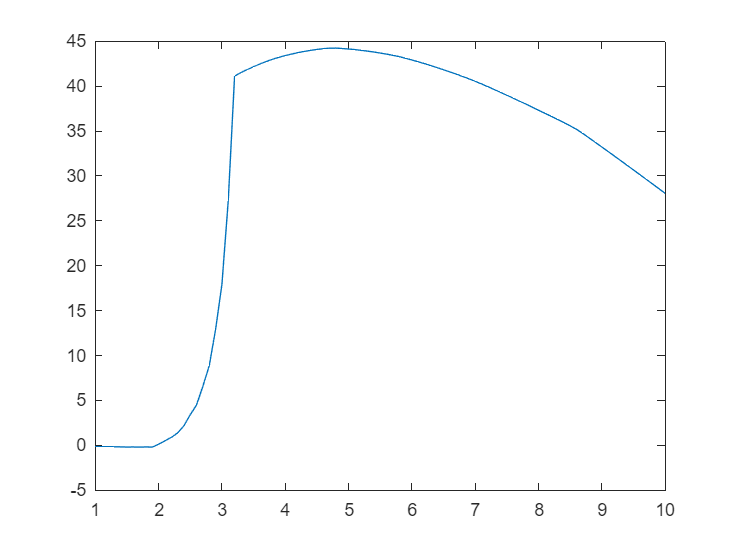

%Using slides (lubbock) method] (Only uses sg43 airfoil rn)
%Seems to scale wierdly with lambda
Wlist=zeros(91,slices); %added this (lothaire)
philist = zeros(91, slices); %added this (lothaire) just to store values
storePw = zeros(1,91);
storea = zeros(91,slices);
storealpha = zeros(91,slices);
for ratiolambda = 1:0.1:10
    alist = [];
    alphalist = [];
    ReList = [];
angvel = (ratiolambda*FreeNormVel)/(Diameter/2);
fn=0;
Pw = 0;
Wtot = 0;
TwistEquation = @(R,DesAlph) (atand(Diameter./(3.55*(R^1.06)*ratiolambda))-DesAlph); 
ChordEquation = @(R,LiftC) (((16*pi*R)/(N*LiftC)).*sin((1/3)*atan(Diameter./(2*R*ratiolambda))).^2);
for R = linspace(RootStart,(Diameter/2),slices)
i = find(R <= AirfoilChangeR, 1); if isempty(i), i = length(AirfoilChangeR)+1; end
a = aopt;
adash = adashopt;
phi = (atand((1-a)*Diameter/(2*ratiolambda*R*(1+adash))));
phi1 = phi + 10; 
brnum = 0 ;
while abs(phi - phi1) > 0.001
    brnum = brnum+1;
Alpha = (-(TwistEquation(R,DesAlpha(i)) - phi));
W = sqrt(((angvel*R)^2)+(FreeNormVel*(1-a))^2);
Re(i) = ((W*ChordEquation(R,LiftCoef(i)))/kVisc);
% DesAlpha(i) = interp1(Re_grid, DesAlpha_table(i,:), Re(i), 'linear', 'extrap');
LiftCoef(length(AirfoilChangeR)+2) = interp2(alpha_grid, Re_grid, squeeze(CL_table(i,:,:)), Alpha, Re(i), 'linear', 0);
DragCoef(length(AirfoilChangeR)+2) = interp2(alpha_grid, Re_grid, squeeze(CD_table(i,:,:)), Alpha, Re(i), 'linear', 0);
% to use the stall correction function, we would probably also need an
% array of Cd0 and AOA0 for the arifoils, these are the final two inputs in the equation
% [LiftCoef(length(AirfoilChangeR)+2),DragCoef(length(AirfoilChangeR)+2)] =
% stall_corrected(XFOIL(idx2,(2+3*(i-1))),XFOIL(idx2,(3+3*(i-1))),Alpha,(R/(Diameter/2)),ChordEquation(R,LiftCoef(i)),angvel,0.04125,-1); 
a = ratiolambda*(LiftCoef(length(AirfoilChangeR)+2)*N*ChordEquation(R,LiftCoef(i)))/(Diameter*pi*4*sind(phi));
adash = 1/(((2*pi*4*sind(phi)*cosd(phi))/(LiftCoef(length(AirfoilChangeR)+2)*N*ChordEquation(R,LiftCoef(i))))-1);
phi1 = phi;
phi = (atand((1-a)*Diameter/(2*ratiolambda*R*(1+adash))));
if brnum == 10
    break
end
end
alphalist = [alphalist,Alpha];
alist = [alist,a];
W = sqrt(((angvel*R)^2)+(FreeNormVel*(1-a))^2);
ReList = [ReList,((W*ChordEquation(R,LiftCoef(i)))/kVisc)];
Wlist(round((ratiolambda-1)/0.1)+1, round((R - RootStart)/((Diameter/2 - RootStart)/(slices-1))) + 1) = W; %added this (lothaire) just to store values
philist(round((ratiolambda-1)/0.1)+1, round((R - RootStart)/((Diameter/2 - RootStart)/(slices-1))) + 1) = phi; %added this (lothaire) just to store values
Wtot = Wtot+W;
Ftip = (2/pi)*acos(exp(-(N/2)*(((Diameter/2)-R)/(R*sind(phi))))); %Prandtls tip loss
Froot = (2/pi)*acos(exp(-(N/2)*((R-(RootStart))/(R*sind(phi))))); %Prandtls root loss
Ftotal = Ftip*Froot; %total tip and root corrections
dR = ((Diameter/2)-(RootStart))/slices;
ForceTot = N * 0.5 * row * W^2 * ChordEquation(R,LiftCoef(i)) * (LiftCoef(length(AirfoilChangeR)+2)*sind(phi)-DragCoef(length(AirfoilChangeR)+2)*cosd(phi));
dPw = (ForceTot * R - 0.03) * angvel * dR; %0.03 accounts for motor resistance
Pw = Pw + dPw*Ftotal;

end
storePw(int32((ratiolambda*10)-9)) = Pw;
storea(int32((ratiolambda*10)-9),:) = alist;
storealpha(int32((ratiolambda*10)-9),:) = alphalist;
storeRe(int32((ratiolambda*10)-9),:) = ReList;
StoreW(int32((ratiolambda*10)-9)) = Wtot/slices;
end
[val, optlambda] = max(storePw);
plot(1:0.1:10,storePw)

Power = val

Power = 44.2333

storeRe(optlambda,:)

ans = 1.0e+04 *

    6.2957    6.4561    6.6083    6.7519    6.8875    7.0156    7.1366    7.2510    7.3591    7.4614    7.5581    7.6496    7.7362    6.3175    6.3799    6.4389    6.4948    6.5476    6.5977    6.6451    6.6900    6.7326    6.7729    6.8113    6.8477    6.8823    6.9151    6.9464    6.9761    7.0044    7.0314    7.0571    7.0816    7.1049    7.1272    7.1485    7.1689    7.1883    7.2070    7.2248    7.2418    7.2581    7.2738    7.2888    7.3031    7.3169    7.3302    7.3429    7.3551    7.3669


mean(storeRe(optlambda,1:37))

ans = 6.9159e+04

mean(storeRe(optlambda,38:end))

ans = 7.4896e+04

storealpha(optlambda,:)

ans =     8.6905    8.5909    8.4939    8.3920    8.2883    8.1838    8.0813    7.9797    7.8805    7.7843    7.6915    7.6022    7.5186    6.9458    6.8735    6.8040    6.7372    6.6732    6.6110    6.5524    6.4962    6.4425    6.3918    6.3422    6.2947    6.2484    6.2053    6.1642    6.1247    6.0870    6.0518    6.0170    5.9836    5.9517    5.9212    5.8918    5.8637    5.8360    5.8102    5.7854    5.7615    5.7385    5.7164    5.6950    5.6743    5.6552    5.6357    5.6170    5.5989    5.5814


% storea(optlambda,:) %Array of a at optimum TSR
% StoreW(optlambda) %AvgVelociity
optlambda = (optlambda+9)/10

optlambda = 4.8000


%Could maybe optimise the following to allow varying of splits and airfoils etc
r(2,:) = (Diameter/8):0.001:(Diameter/2);
r(1,:) = NaN;
Rt2Chnge = (RootStart):0.001:(Diameter/8);
r(1,1:length(Rt2Chnge)) = Rt2Chnge;
% % NEW METHOD
figure
ChordEquation = @(R,LiftC) (((16*pi*R)/(N*LiftC)).*sin((1/3)*atan(Diameter./(2*R*optlambda))).^2);
for i = 1:2
plot(r(i,:),ChordEquation(r(i,:),LiftCoef(i)))
hold on
end
Chord(1,:) = [r(1,1:length(Rt2Chnge)),r(2,:)];
Chord(2,:)= [ChordEquation(r(1,1:length(Rt2Chnge)),LiftCoef(1)),ChordEquation(r(2,:), LiftCoef(2))]

Chord =     0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590    0.0600    0.0610    0.0620    0.0625    0.0635    0.0645    0.0655    0.0665    0.0675    0.0685    0.0695    0.0705    0.0715    0.0725    0.0735    0.0745    0.0755    0.0765    0.0775    0.0785    0.0795    0.0805    0.0815    0.0825    0.0835
    0.0905    0.0907    0.0908    0.0909    0.0909    0.0909    0.0908    0.0907    0.0906    0.0904    0.0901    0.0899    0.0896    0.0893    0.0889    0.0886    0.0882    0.0878    0.0874    0.0869    0.0865    0.0860    0.0856    0.0851    0.0846    0.0841    0.0836    0.0831    0.0667    0.0663    0.0659    0.0655    0.0650    0.0646    0.0642    0.0638    0.0633    0.0629    0.0625    0.0620    0.0616    0.0612    0.0608    0.0603    0.0599    0.0595    0.0591    0.0587    0.0582 

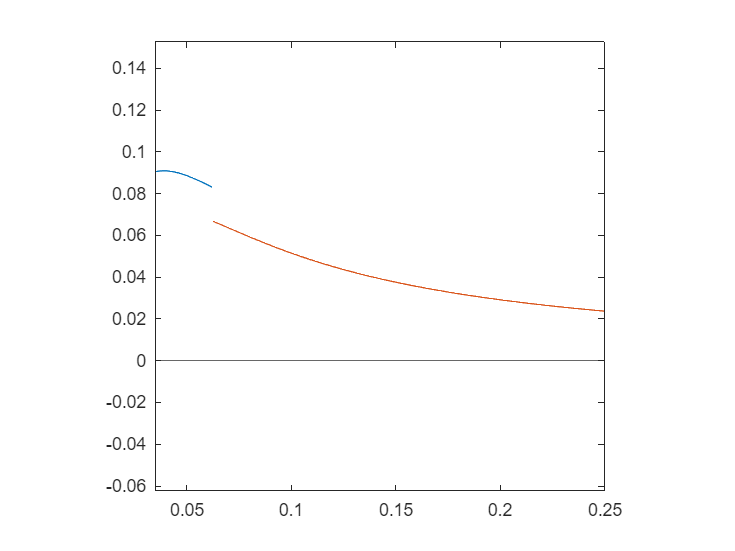

% MeanChord = mean([ChordEquation(r(2,:)),ChordEquation(r(1,1:length(Rt2Chnge)))])
yline(0)
set(gca,'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1],'XLim',[RootStart,(Diameter/2)])
hold off


% To find twist
figure
TwistEquation = @(R,DesAlph) (atand(Diameter./(3.55*(R.^1.06)*ratiolambda))-DesAlph);  
for i = 1:2
plot(r(i,:),TwistEquation(r(i,:),ForTwstGrphAlpha(i)))
hold on
end
Twist(1,:) = [r(1,1:length(Rt2Chnge)),r(2,:)];
Twist(2,:) = [TwistEquation(r(1,1:length(Rt2Chnge)),ForTwstGrphAlpha(1)),TwistEquation(r(2,:),ForTwstGrphAlpha(2))]

Twist =     0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490    0.0500    0.0510    0.0520    0.0530    0.0540    0.0550    0.0560    0.0570    0.0580    0.0590    0.0600    0.0610    0.0620    0.0625    0.0635    0.0645    0.0655    0.0665    0.0675    0.0685    0.0695    0.0705    0.0715    0.0725    0.0735    0.0745    0.0755    0.0765    0.0775    0.0785    0.0795    0.0805    0.0815    0.0825    0.0835
   18.4506   17.7790   17.1378   16.5251   15.9393   15.3787   14.8419   14.3274   13.8341   13.3608   12.9062   12.4695   12.0495   11.6455   11.2566   10.8819   10.5209   10.1727    9.8367    9.5124    9.1991    8.8963    8.6036    8.3205    8.0464    7.7810    7.5240    7.2749    7.9032    7.6653    7.4346    7.2106    6.9932    6.7820    6.5767    6.3773    6.1833    5.9946    5.8110    5.6323    5.4583    5.2888    5.1236    4.9627    4.8058    4.6528    4.5035    4.3578    4.2157 

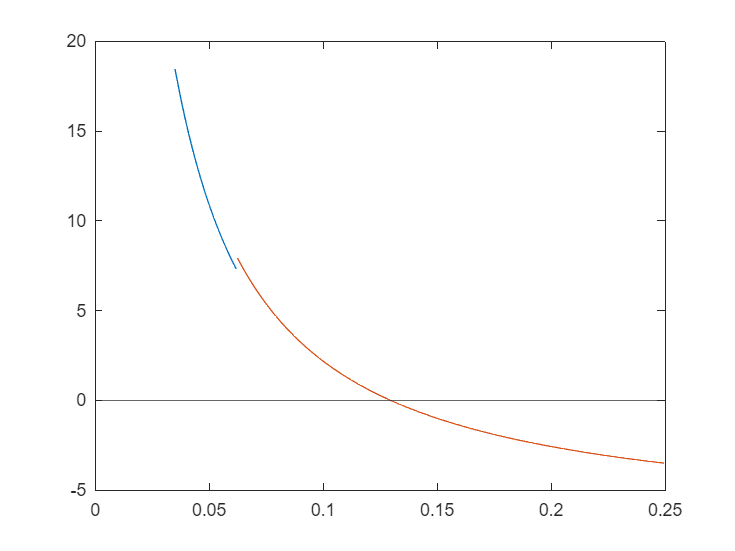

yline(0)
hold off

% % LUBBOCK METHOD
% % To find chord distribution
% AreaBlade = (((Diameter/2)^2)/(N*ratiolambda))
% ChordIntegral = @(k) (integral(@(x) (k./x),(Diameter/20),(Diameter/2))-AreaBlade)
% k = fzero(ChordIntegral,0.1)
% ChordEquation = @(R) (k./R)
% plot(r,ChordEquation(r))
% yline(0)
% set(gca,'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1],'XLim',[Diameter/20,(Diameter/2)])
% hold off

% % To find twist
% figure
% for i = 1:2
% TwistEquation = @(R) (atand(Diameter./(3*R*ratiolambda))-DesAlpha(i));
% plot(r(i,:),TwistEquation(r(i,:)))
% hold on
% end
% yline(0)
% hold off

% FOR WHATEVER REASON THIS CODE USING I2A IS WRONG (IDK WHY)
% boundr(1:2) = [(Diameter/2),(Diameter/20)];
% for i = 1:2
% ChordEquation = @(R) (((16*pi*R)/(N*LiftCoef(i))).*sin((1/3)*atan(Diameter./(2*R*ratiolambda))).^2); %try to remove later for ease of code
% Fn(i) = 0; %Found iteratively, Loop till convergence
%  Fn1(i) = 10;
% while abs(Fn(i) - Fn1(i)) > 0.00001
%  angvel = (ratiolambda*FreeNormVel)/(Diameter/2);
%  NormVel = (FreeNormVel/2) - (1/2)*sqrt((FreeNormVel^2) + (8*Fn(i))/(row*pi*Diameter^2)); %the second part applies the induced stuff
%  TangVel = @(x) (angvel*x); %func of R
%  TotalVel =  @(x) (sqrt((x.^2)+NormVel^2)); %func of TangVel
%  dAOA =  @(x) (atand(NormVel./x)); %func of TangVel
% 
%  SingleIntegral = @(a,b,c) (1/2*row*(a.^2).*c.*(LiftCoef(i)*cosd(b)+(sind(b)*DragCoef(i))));
%  Fn1(i) = Fn(i);
%  Fn(i) = (N)*integral(@(x) SingleIntegral(TotalVel(TangVel(x)),dAOA(TangVel(x)),ChordEquation(x)),(Diameter/8),boundr(i));
% end
% SingleIntegralp = @(a,b,c) (1/2*row*(a.^2).*c.*(DragCoef(i)*cosd(b)-(sind(b)*LiftCoef(i))));
% Pw(i) = (N)*angvel*integral(@(x) SingleIntegralp(TotalVel(TangVel(x)),dAOA(TangVel(x)),ChordEquation(x).*x),(Diameter/8),boundr(i));
% end
% Fn =  Fn(1) - Fn(2)
% Pw = Pw(1) - Pw(2)

function [Cl,Cd] = stall_corrected(xfoil_cl,xfoil_cd,Alpha,r_ratio,c,angvel,Cd0,AoA0) %function to apply stall correction
    if r_ratio>0.3 && r_ratio<0.95 %from a paper, how the shift value varies along the blade
        % these equations are from the 1998 AIAA paper
        clp = 2*pi*(Alpha-AoA0);
        cr_ratio = c/(r_ratio*(0.245)); %this has the radius in it, in case that changes in the future
        big_lamb = ((angvel)*0.245)/sqrt(100 + ((angvel)*0.245)^2);
        fl = ( (1.6*cr_ratio/0.1267) * ( (1-cr_ratio^(1/(big_lamb*r_ratio)) ) / (1+cr_ratio^(1/(big_lamb*r_ratio))) )-1) / (2*pi); 
        fd = ( (1.6*cr_ratio/0.1267) * ( (1-cr_ratio^(1/(2*big_lamb*r_ratio)) ) / (1+cr_ratio^(1/(2*big_lamb*r_ratio))) )-1) / (2*pi); 
        del_cl =fl*(clp-xfoil_cl);
        del_cd =fd*(xfoil_cd-Cd0);
        Cl = xfoil_cl+del_cl;
        Cd = xfoil_cd-del_cd;
    else
        Cl = xfoil_cl;
        Cd = xfoil_cd;
    end
end
